signed = 1;
word_len = 16;
frac_len = 7;
T = numerictype(signed, word_len, frac_len);
q = quantizer('DataMode', 'fixed', 'RoundMode', 'floor', 'Format', [word_len frac_len], 'OverflowMode', 'wrap');

ns = 2000;
rng(0);
x = fi(randquant(q, ns, 1), T);

T2 = numerictype(1, 35, 14);
taps = 4;

coeffs = [1 2 3 4];
coeffs = fi(coeffs, T);
mults = fi(zeros(ns,taps), T2);
sums = fi(zeros(ns, taps-1), T2);
y = fi(zeros(length(x),1), T);

for i = 2:ns
    for j = length(sums(i,:)):-1:2
        sums(i,j) = sums(i-1,j-1) + mults(i-1, j);       
    end  
    
    sums(i,1) = mults(i-1,1); 

    mults(i,:) =  x(i-1).*fi(coeffs, T2);
    mults(i,:) = flip(mults(i,:));

    y(i) = quantize(sums(i,end) + mults(i,end), T, 'Floor', 'Wrap');     
end

save_dec_txt(x, T, "data/input.txt");
save_dec_txt(coeffs.', T, "data/coeffs.txt");
save_dec_txt(y, T, "data/output.txt");


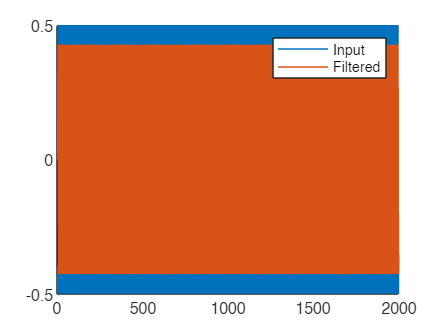

%% Filter sine
signed = 1;
word_len = 32;
frac_len = 25;
T = numerictype(signed, word_len, frac_len);
q = quantizer('DataMode', 'fixed', 'RoundMode', 'floor', 'Format', [word_len frac_len], 'OverflowMode', 'wrap');

ns = 2000;
sine = dsp.SineWave(0.5, 1000, 'SampleRate', 8000,'SamplesPerFrame',ns);
s = sine();

coeffs = [0.5 0.5 0 0];
y = filter(coeffs, 1, s);
plot([s y])
legend('Input', 'Filtered')

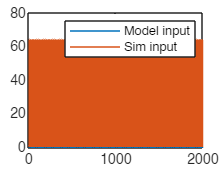


save_dec_txt(s, T, "data/input.txt");
save_dec_txt(coeffs.', T, "data/coeffs.txt");

in = load_dec_txt("data/input.txt", T);
plot([s in])
legend('Model input', 'Sim input')


out = load_dec_txt("data/output.txt", T);
p = plot([y out])

p =   2×1 Line array:

  Line
  Line


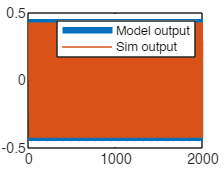

p(1).LineWidth = 4;
legend('Model output', 'Sim output')